Antena Transmissora

ant1 = spiralArchimedean('Turns',4,'Tilt',90,'TiltAxis','Y')

ant1 =   spiralArchimedean with properties:

             NumArms: 2
               Turns: 4
         InnerRadius: 5.0000e-04
         OuterRadius: 0.0398
    WindingDirection: 'CCW'
                Tilt: 90
            TiltAxis: 'Y'
                Load: [1×1 lumpedElement]


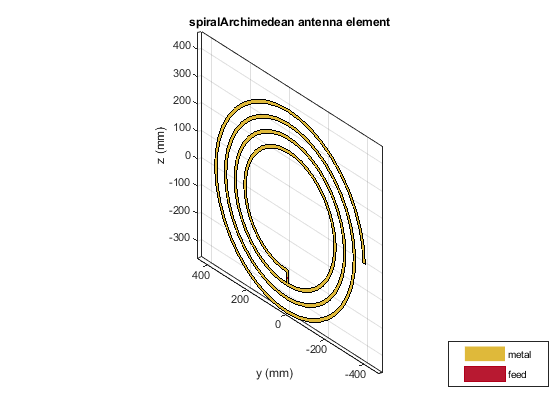

ant1.NumArms = 1;
ant1.OuterRadius = 40e-2;
ant1.InnerRadius = 20e-2;
show(ant1)

Impedância da antena

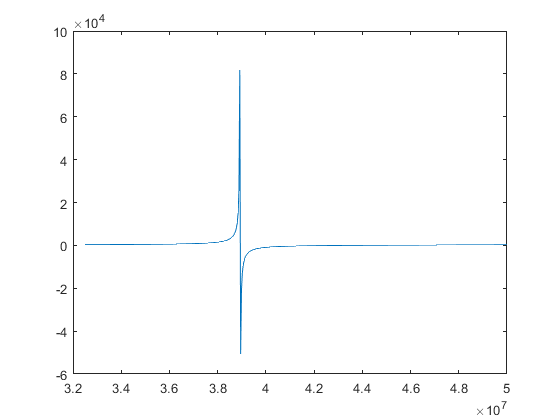

f = linspace(3.25e7,5e7,500);

impedancia = impedance(ant1,f);

imaginario = imag(impedancia);

figure 
plot(f,imaginario)

Antena Receptora

ant2 = spiralArchimedean('Turns',4,'Tilt',90,'TiltAxis','Y')

ant2 =   spiralArchimedean with properties:

             NumArms: 2
               Turns: 4
         InnerRadius: 5.0000e-04
         OuterRadius: 0.0398
    WindingDirection: 'CCW'
                Tilt: 90
            TiltAxis: 'Y'
                Load: [1×1 lumpedElement]


ant2.NumArms = 1;
ant2.Tilt = 90;
ant2.OuterRadius = 40e-2;
ant2.InnerRadius = 20e-2;
show(ant2)

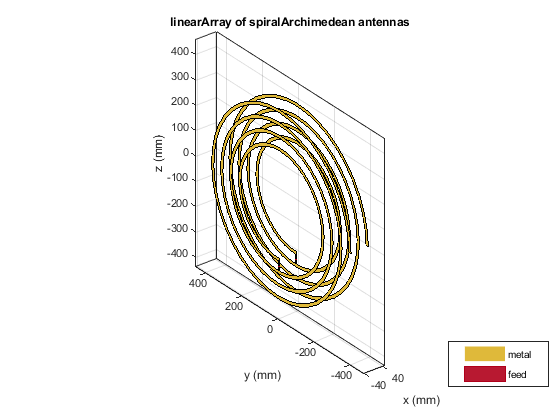

array = linearArray('Element',[ant1,ant2],'ElementSpacing',0.075);
show(array)

Simulando

ganhos = sparameters(array,f)

ganhos =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [500×1 double]
     Parameters: [2×2×500 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


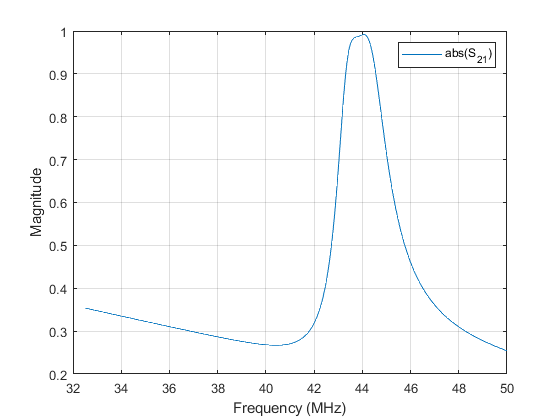


rfplot(ganhos,2,1,'abs')

values = rfparam(ganhos,2,1);
ganho_maximo = abs(max(values))

ganho_maximo = 0.9917

Em 3D

g = zeros(10,500);

d = linspace(0.01, 0.1, 10);

for n = [1 2 3 4 5 6 7 8 9 10]
    
    array = linearArray('Element',[ant1,ant2],'ElementSpacing',d(1,n));
    sp = sparameters(array,f);
    g(n,:) = abs(rfparam(sp,2,1));
    
end

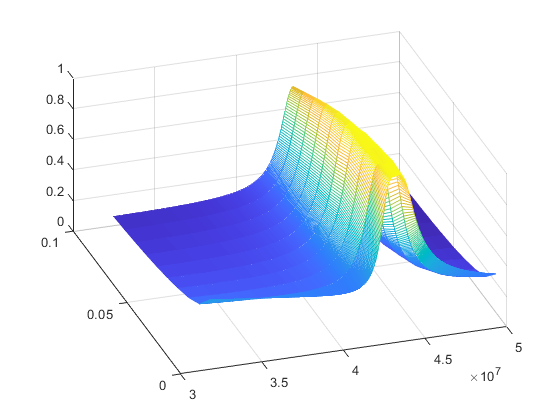

mesh(f,d,g)